clear;clc;close all;fclose('all');

params

BW = 250000;
Fc = 250000;
Interp = 40;
nyquist_percent = 90; % Percent of baseband nyquist zone in pass band - Rest in transition band

M_filt = 512;
beta = 2;

% CIC Params
M = 1; % Differential delay
N = 2; % Number of stages

Read Signal from SW

file = fopen('../Xilinx/SW_Source/ofdm/files/TxIfftSamples1.txt','r');
nfft = fscanf(file,"%d,",1);
ofdm_symbols = fscanf(file,"%d,",1);
cp_len = fscanf(file,"%d,",1);
ofdm_signal = fscanf(file,"%lf, %lf\n",[2,(nfft+cp_len)*ofdm_symbols]);
ofdm_signal = complex(ofdm_signal(1,:),ofdm_signal(2,:));

Plot baseband spectrum:

Ts = 1/BW;
t = 0:Ts:((nfft+cp_len)*ofdm_symbols)*Ts-Ts; % Time vector at baseband
nfft_plot = nfft*4; % Nfft for plotting spectrum
F = (-nfft_plot/2:nfft_plot/2-1)/nfft_plot*BW;
W = (-nfft_plot/2:nfft_plot/2-1)/nfft_plot*2;

Interpolate with MATLAB function

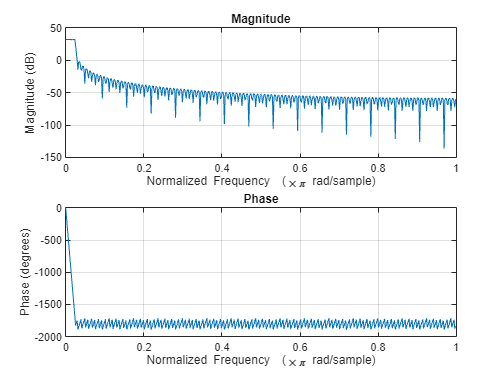

Fs_up = BW*Interp;
Ts_up = 1/Fs_up;
t_up = 0:Ts_up:((nfft+cp_len)*ofdm_symbols)*Ts_up-Ts_up;
F_up = (-nfft_plot/2:nfft_plot/2-1)/nfft_plot*Fs_up;

[Interp_sig_mat,taps] = interp(ofdm_signal,Interp,10,1);
freqz(taps,1)

Interpolate with CIC 

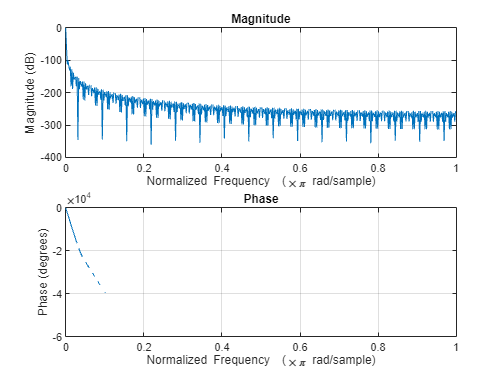

Rd = Interp^N;
h = ones(Rd,1);
for i = 1:N 
    h = conv(h,h);
end
h = h / sum(h);
% Interpolate the signal
up_cic_sig = zeros(Interp*length(ofdm_signal),1);
up_cic_sig(1:Interp:end) = ofdm_signal;
Interp_cic_sig = filter(h,1,up_cic_sig);
freqz(h,1)

Plot Interpolated spectrum:

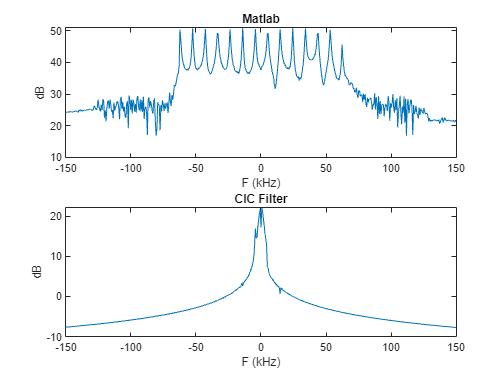

x_lim = [-150 150];
figure(),subplot(2,1,1),plot(F_up/1000,10*log10(abs(fftshift(fft(Interp_sig_mat,nfft_plot))))),xlabel('F (kHz)'),ylabel('dB'),title('Matlab'),xlim(x_lim)
subplot(2,1,2),plot(F_up/1000,10*log10(abs(fftshift(fft(Interp_cic_sig,nfft_plot))))),xlabel('F (kHz)'),ylabel('dB'),title('CIC Filter'),xlim(x_lim)

Read captured Xilinx CIC Filter Impulse Response:

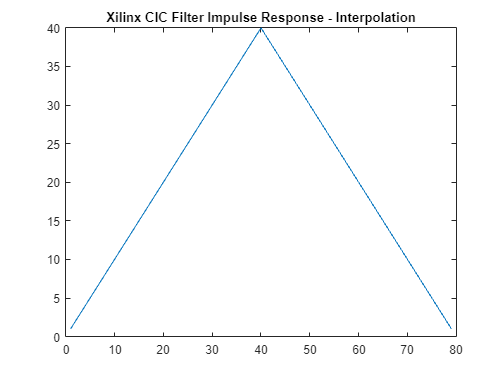

file = fopen('../Xilinx/Vivado/modules/sim/cic_duc_test_out.txt','r');
cic_impulse = fscanf(file,"%d, %d\n",[2 79]);
cic_impulse_real = cic_impulse(1,:);

figure(),plot(cic_impulse_real),title('Xilinx CIC Filter Impulse Response - Interpolation')

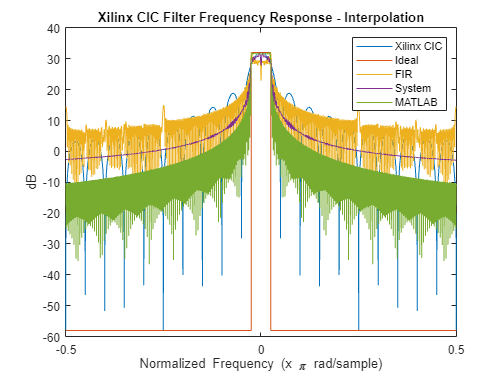


cic_freq_real = fft(cic_impulse_real,nfft_plot); % Frequency response of CIC filter
max_val = max(cic_freq_real);
min_val = 10^(-58/10); % zero samples cause NAN in calculation
cic_0_ind = find(cic_freq_real == 0);
cic_freq_real(cic_0_ind) = min_val;

% Ideal Frequency response
ideal_freq = [min_val*ones(1,floor(length(W)*(1-1/Interp)/2)),max_val*ones(1,floor(length(W)*1/Interp)),min_val*ones(1,floor(length(W)*(1-1/Interp)/2)),0];

cic_freq_real_inv = 1./conj(cic_freq_real); % Inverse of CIC frequency response 

% Multiply the inverse CIC frequency response with the desired frequency
% response to obtain the desired frequency response of the FIR filter
fir_freq_response = fftshift(ideal_freq).*cic_freq_real_inv;
% Resample to number of taps in filter
fir_freq_response_decimate = resample(fir_freq_response,M_filt,nfft_plot);
% Obtain impulse response
fir_impulse_response = ifft(ifftshift(fir_freq_response_decimate,M_filt));
% Scale
fir_impulse_response = fir_impulse_response .* kaiser(M_filt,beta).';

% Design FIR filter with Parks-McClellan method
% f = [0 1/Interp*nyquist_percent/100 1/Interp 0.5];
% a = [1 0.7 0.5 0.3];
% fir_impulse_response = fir1(M_filt-1,1/Interp) .*chebwin(M_filt,20).';%.* kaiser(M_filt,beta).';

system_impulse_response = filter(cic_impulse_real,1,[1 zeros(1,M_filt-1)]);
system_impulse_response = filter(fir_impulse_response,1,system_impulse_response);
system_freq_response = fft(system_impulse_response,nfft_plot);
system_freq_response = max_val/max(system_freq_response)*system_freq_response;

fir_freq_response_actual = fft(fir_impulse_response,nfft_plot);
fir_freq_response_actual = max_val/max(fir_freq_response_actual)*fir_freq_response_actual;

matlab_impulse_response = filter(taps,1,[1 zeros(1,length(taps))]);
matlab_freq_response = fft(matlab_impulse_response,nfft_plot);
matlab_freq_response = max_val/max(matlab_freq_response)*matlab_freq_response;

figure(),plot(W,10*log10(abs(fftshift(cic_freq_real)))),hold on,plot(W,10*log10(ideal_freq))
plot(W,10*log10(abs(fftshift(fir_freq_response_actual)))),plot(W,10*log10(abs(fftshift(system_freq_response))))
plot(W,10*log10(abs(fftshift(matlab_freq_response)))),title('Xilinx CIC Filter Frequency Response - Interpolation')
xlabel('Normalized Frequency (x \pi rad/sample)'),ylabel('dB'),legend('Xilinx CIC','Ideal','FIR','System','MATLAB')
xlim([-0.5 0.5])